clear
p1 = [42.29346855201444, -71.26434446734517];
p2 = [42.29353551369737, -71.26429082316935];


[gridCoordinate1] = GPSToGrid(p1)

gridCoordinate1 = struct with fields:
    x: 6.5884
    y: 37.5316


[gridCoordinate2] = GPSToGrid(p2)

gridCoordinate2 = struct with fields:
    x: 11.0124
    y: 44.9696


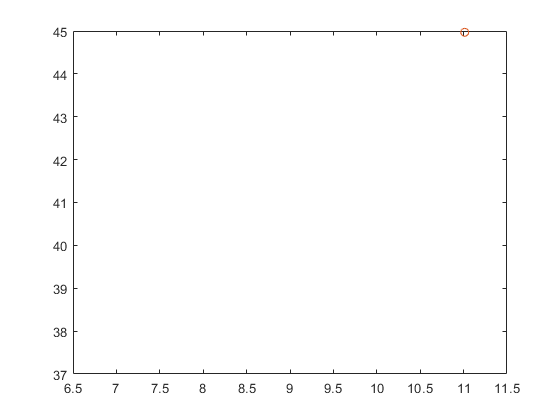


x = [gridCoordinate1.x  gridCoordinate2.x] gridCoordinate2.y
plot(gridCoordinate1.x, gridCoordinate1.y, gridCoordinate2.x, gridCoordinate2.y, "o")

% roverLocation = [42.293346 -71.264365]
% targetWaypoint = [42.293389 -71.264359]
roverLocation = [0 0]
targetWaypoint = [.5 .1 ]
roverBearing = 0
    % Initialize the waypoint vector
    waypointSteeringVector = zeros(71,1);
    
    % Do math to find radius of bumblebee circle
    xdist = abs(targetWaypoint(1) - roverLocation(1))
    ydist = abs(targetWaypoint(2) - roverLocation(2))
    omega = 360 - roverBearing
    a = 1-cosd(omega)^2-sind(omega)^2
    b = 2*(cosd(omega)*xdist + sind(omega)*ydist)
    c = -(xdist^2 + ydist^2)
    radius = roots([b c])
    %converting radius to meters
%     radius_meters = radius*111000
    % converting to bearing
%     bearing = (radius - eqn(2))./(eqn(1))
  car_length = 0.308
  half_length = car_length/2;
  r= radius;
  bearing = asind(half_length/(2*r))
     
    % finding the index for the turn angles to change
    turnAngles = -35:10:35 % 8 vectors( y range is from -1 to 1)
    ind = find(abs(turnAngles - bearing) <= 0.001);
    
    % Change the steering vector
    waypointSteeringVector(ind) = 0.5;

    f(x) = a*exp(b*x) + c*exp(d*x)

       where x is normalized by mean 21.25 and std 11.09

Coefficients:

       a =    0.002742

       b =      -5.253

       c =       1.425

       d =     -0.4118

    angles = [10 15 25 35];
radius = [2.73 1.85 1.24 0.855]; % in meters
eqn = polyfit(angles,radius,1)
plot(angles, radius)
cftool(angles,radius)


%--------------------------------------------------------------------------
%
% Position: Position vector (r [m]) from geodetic coordinates
%           (Longitude [rad], latitude [rad], altitude [m])
%
% Last modified:   2018/01/27   M. Mahooti
%
%--------------------------------------------------------------------------

% function r = GPStometres(lon, lat, h)
% R_equ = 6378.137e3;      % Earth's radius [m]; WGS-84
% f     = 1/298.257223563; % Flattening; WGS-84
% e2     = f*(2-f);        % Square of eccentricity
% CosLat = cos(lat);       % (Co)sine of geodetic latitude
% SinLat = sin(lat);
% % Position vector 
% N = R_equ/sqrt(1-e2*SinLat*SinLat);
% r(1) = (N+h)*CosLat*cos(lon);
% r(2) = (N+h)*CosLat*sin(lon);
% r(3) = ((1-e2)*N+h)*SinLat;
% end
% 
% function [d] = GPSmeasure(lat1, lon1, lat2, lon2)%generally used geo measurement function
%     R = 6378.137; %Radius of earth in KM
%      dLat = lat2 * pi / 180 - lat1 * Math.pi/ 180;
%     dLon = lon2 * Math.PI / 180 - lon1 * Math.PI / 180;
%     a = Math.sin(dLat/2) * Math.sin(dLat/2) +
%    cos(lat1 * Math.PI / 180) * Math.cos(lat2 * Math.PI / 180) *
%     sin(dLon/2) * sin(dLon/2);
%      c = 2 * Math.atan(sqrt(a), sqrt(1-a));
%      d = R * c;
%      d * 1000; %meters


function [gridCoordinate] = GPSToGrid(GPSCoordinate)
    altitude = 10;
    % origin is at the bottom left corner
    origin = [42.29313067072105, -71.26442435650652, altitude];
    [gridCoordinate.x,gridCoordinate.y] = latlon2local(GPSCoordinate(1), GPSCoordinate(2),altitude,origin);
end
